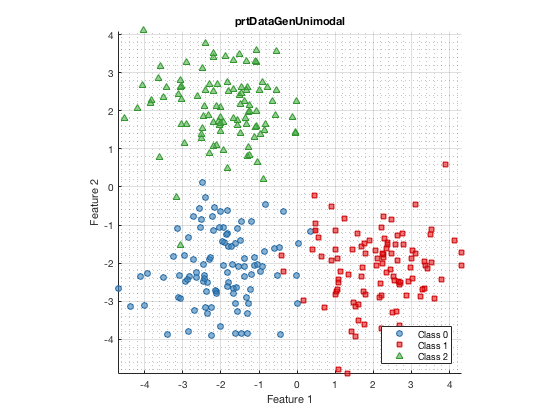

theta = pi/2;
mu0 = [-2,-2];
mu1 = [2,-2];
mu2 = 4*[cos(theta),sin(theta)] + mu0;
Sigma = eye(2);
N = 100;
ds1 = prtDataGenUnimodal(N,mu0,mu1,Sigma,Sigma);
ds2 = prtDataGenUnimodal(N,mu0,mu2,Sigma,Sigma);
ds2.Y(ds2.Y==1) = 2;
ds = catObservations(ds1,ds2.retainObservations(ds2.Y==2));
plot(ds)
axis equal tight

X = ds.X;
Y = ds.getTargetsAsBinaryMatrix;
Y = Y-mean(Y,1);

S = X'*Y

S =    1.0e+02 *

  -1.369040351542703   2.705116337216156  -1.336075985673453
  -1.402395689774996  -1.386188053440878   2.788583743215875


% S(i,j) is the covariance between feature i and class j

nComponents = 1;
R = zeros(size(X,2),nComponents);
Q = zeros(size(Y,2),nComponents);
for iVec = 1:nComponents
    [U,S,V] = svd(S)
    
    r = U(:,1); % We only need the first solution
    t = X*r; % the current score for X
    t = t - mean(t);
    t = t./norm(t);
    q = Y'*t; % the current loadings for Y
    
    % To deflate S project onto the normalized V 
    % We need to make sure that V is really orthogonal
    % This is simple Gram-Schimdt
    v = X'*t;
    if iVec > 1
        v = v - V(:,1:(iVec-1))*(V(:,1:(iVec-1)).'*v);
        u = u - T(:,1:(iVec-1))*(T(:,1:(iVec-1)).'*u);
    end
    v = v ./ norm(v);
    % Deflate S
    S = S - v*(v'*S);
    
    R(:,iVec) = r; % X,Y Covariance Orthogonal Decomposition
    Q(:,iVec) = q; % Y Loadings
end

U =   -0.684927852419291   0.728610895458130
   0.728610895458130   0.684927852419291


S =    1.0e+02 *

   4.109376180391092                   0                   0
                   0   2.398850268916984                   0


V =   -0.020467075235756  -0.816240017089312   0.577350269189626
  -0.696651052766911   0.425845015639988   0.577350269189626
   0.717118128002667   0.390395001449324   0.577350269189626


Bpls = R*Q'

Bpls =    0.130549268628068   4.443589735225514  -4.574139003853580
  -0.138875385459243  -4.726991148914812   4.865866534374054
